%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% BME705: Rehabilitation Engineering
% Lab 1: Applications of FES and EMG in Rehabilitation
%
% Created by: Devon Santillo, 2020
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Names: Tanvir Hassan, Ilina Petrova
 
% Student IDs: 501104056, 501126967

close all
clear all

%% Initializations
% Load all relevent files and, if necessary, save the components of them
% into variables

tData = load("TA_data1.mat"); % loading the TA-1 dataset tht was assigned, and load it into the tData variable
fData = load("FESfatigue_data10.mat");
stim_data = load("FStim_data.mat");

%the three sampling frequencies for each data given in the lab manual
fs = 2000; 
fs_fatigue = 1000;
fs_simulation = 100;


%% Part 1: Introduction to EMG analysis
% separate EMG and force data using the dot operator
EMG = (tData.increase_ta_emg);
Force = (tData.increase_ta_force);

% Define time as a linear vector

t = (0:length(EMG)-1) / fs;

% Processing:

G = 500; % Gain applied during aquisition

EMG= (EMG/G)*1000; % convert to mV and get rid of the gain


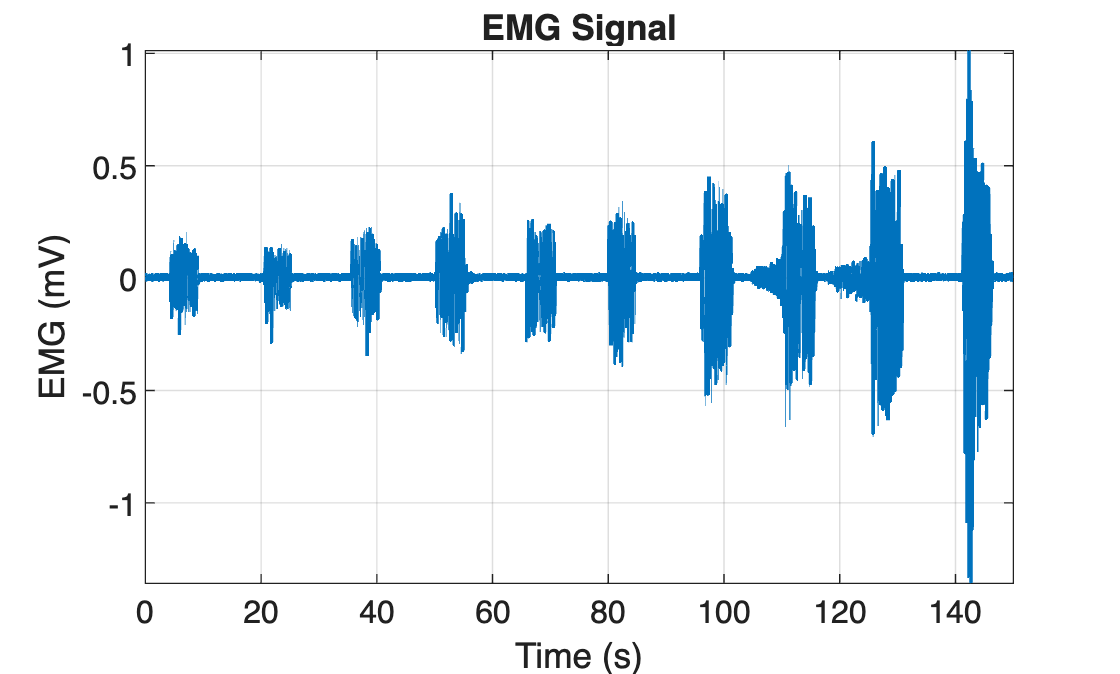

%1) original graphs

figure;
plot(t, EMG, 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]); % Improved line width and color
title('EMG Signal', 'FontSize', 14, 'FontWeight', 'bold'); % Enhanced title
xlabel('Time (s)', 'FontSize', 12); % Increased font size for x-axis label
ylabel('EMG (mV)', 'FontSize', 12); % Increased font size for y-axis label
grid on; % Ensure grid is on
xlim([0 max(t)]); % Set x-axis limits
ylim([min(EMG) max(EMG)]); % Set y-axis limits based on EMG data
set(gca, 'FontSize', 12); % Set font size for axes

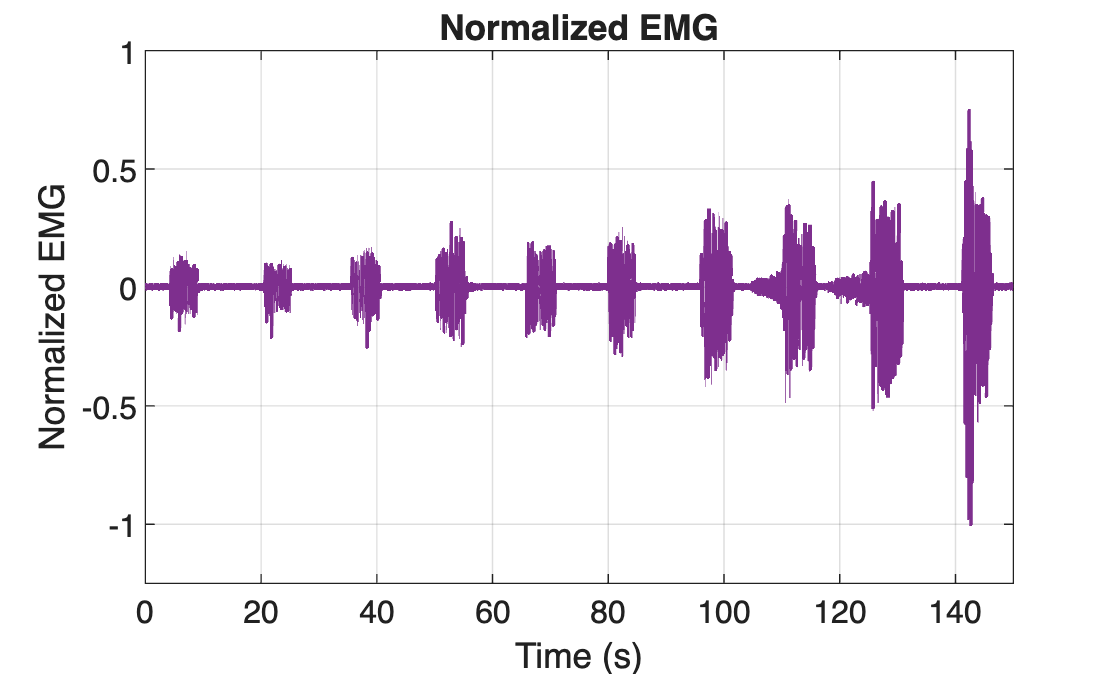


%2) Normalizing the EMG data
EMG_normalized = EMG/(max(abs(EMG))-min(abs(EMG)));
figure;
plot(t, EMG_normalized, 'LineWidth', 1.5, 'Color', [0.4940 0.1840 0.5560]); % Improved line width and color
title('Normalized EMG', 'FontSize', 14, 'FontWeight', 'bold'); % Enhanced title
xlabel('Time (s)', 'FontSize', 12); % Increased font size for x-axis label
ylabel('Normalized EMG', 'FontSize', 12); % Increased font size for y-axis label
grid on; % Ensure grid is on
xlim([0 max(t)]); % Set x-axis limits
ylim([-1.25 1]); % Set y-axis limits for normalized data
set(gca, 'FontSize', 12); % Set font size for axes

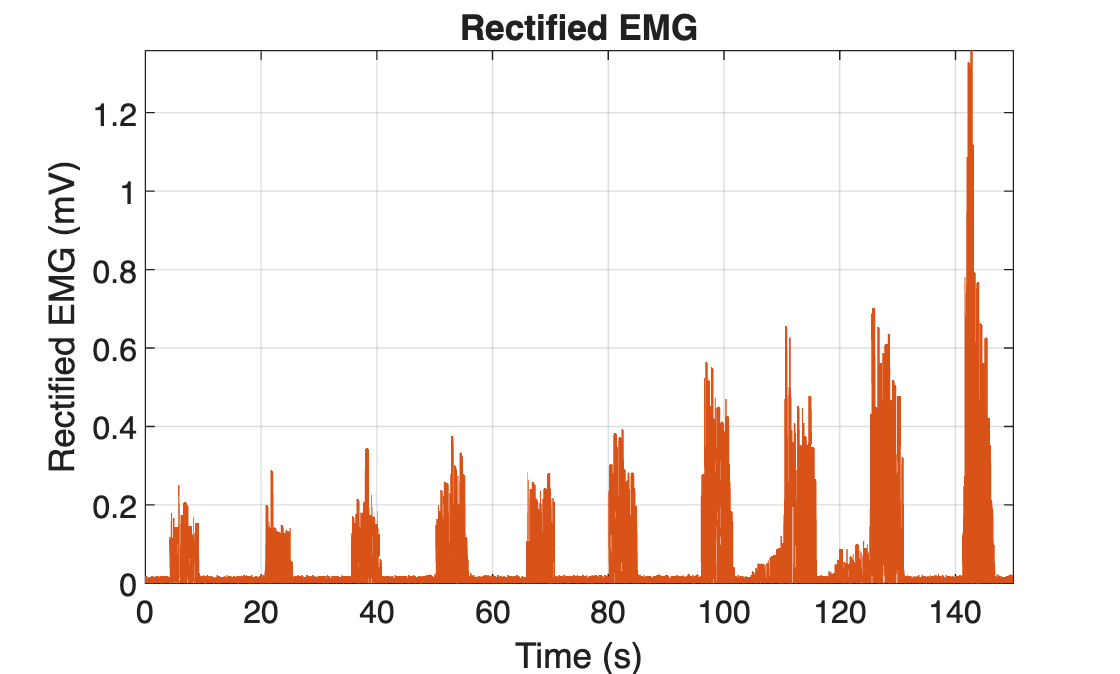

%3) rectification 
EMG_abs = abs(EMG);
figure;
plot(t, EMG_abs, 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]); % Improved line width and color
title('Rectified EMG', 'FontSize', 14, 'FontWeight', 'bold'); % Enhanced title
xlabel('Time (s)', 'FontSize', 12); % Increased font size for x-axis label
ylabel('Rectified EMG (mV)', 'FontSize', 12); % Increased font size for y-axis label
grid on; % Ensure grid is on
xlim([0 max(t)]); % Set x-axis limits
ylim([0 max(EMG_abs)]); % Set y-axis limits based on rectified EMG data
set(gca, 'FontSize', 12); % Set font size for axes

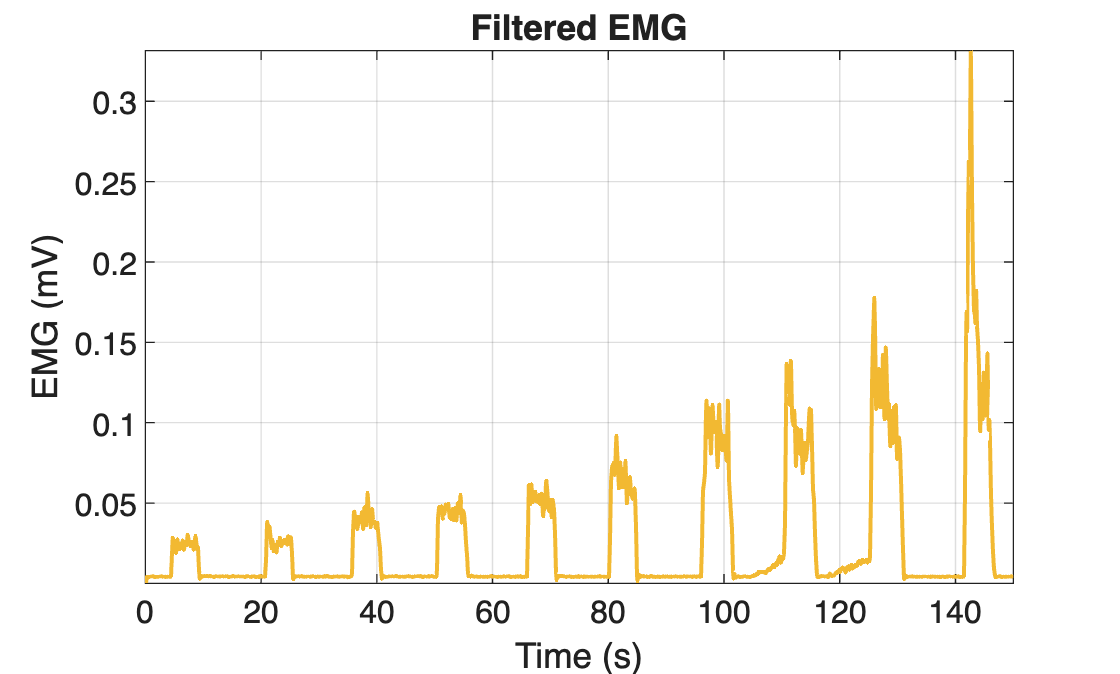

%4) Filtered EMG signal
fc = 2.5; % corner frequency
%establishing the transfer function of a 4th order butterworth filter

[b, a] = butter(4, fc/(fs/2));
EMG_filtered = filter(b, a, EMG_abs);

figure;
plot(t, EMG_filtered, 'LineWidth', 1.5, 'Color', [0.9500 0.7250 0.1980]); % Improved line width and color
title('Filtered EMG', 'FontSize', 14, 'FontWeight', 'bold'); % Enhanced title
xlabel('Time (s)', 'FontSize', 12); % Increased font size for x-axis label
ylabel('EMG (mV)', 'FontSize', 12); % Increased font size for y-axis label
grid on; % Ensure grid is on
xlim([0 max(t)]); % Set x-axis limits
ylim([min(EMG_filtered) max(EMG_filtered)]); % Set y-axis limits based on filtered EMG data
set(gca, 'FontSize', 12); % Set font size for axes

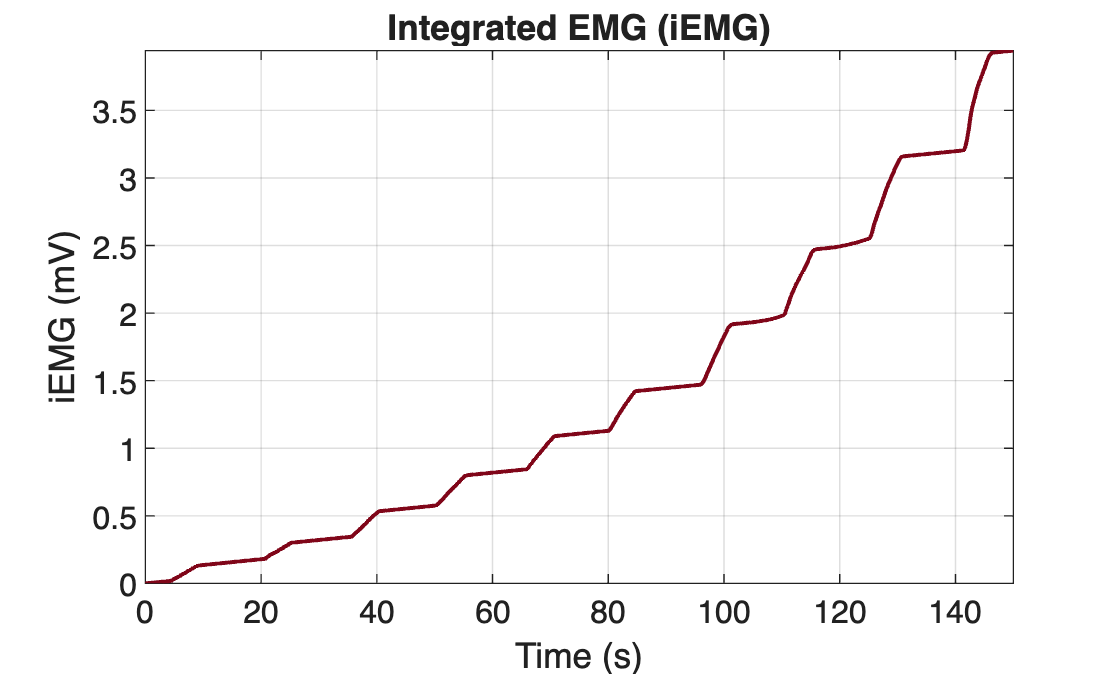

%5) calculating iEMG
iEMG = cumtrapz(t, EMG_abs);
figure;
plot(t, iEMG, 'LineWidth', 1.5, 'Color', [0.500 0.0250 0.09980]); % Improved line width and color
title('Integrated EMG (iEMG)', 'FontSize', 14, 'FontWeight', 'bold'); % Enhanced title
xlabel('Time (s)', 'FontSize', 12); % Increased font size for x-axis label
ylabel('iEMG (mV)', 'FontSize', 12); % Increased font size for y-axis label
grid on; % Ensure grid is on
xlim([0 max(t)]); % Set x-axis limits
ylim([min(iEMG) max(iEMG)]); % Set y-axis limits based on iEMG data
set(gca, 'FontSize', 12); % Set font size for axes

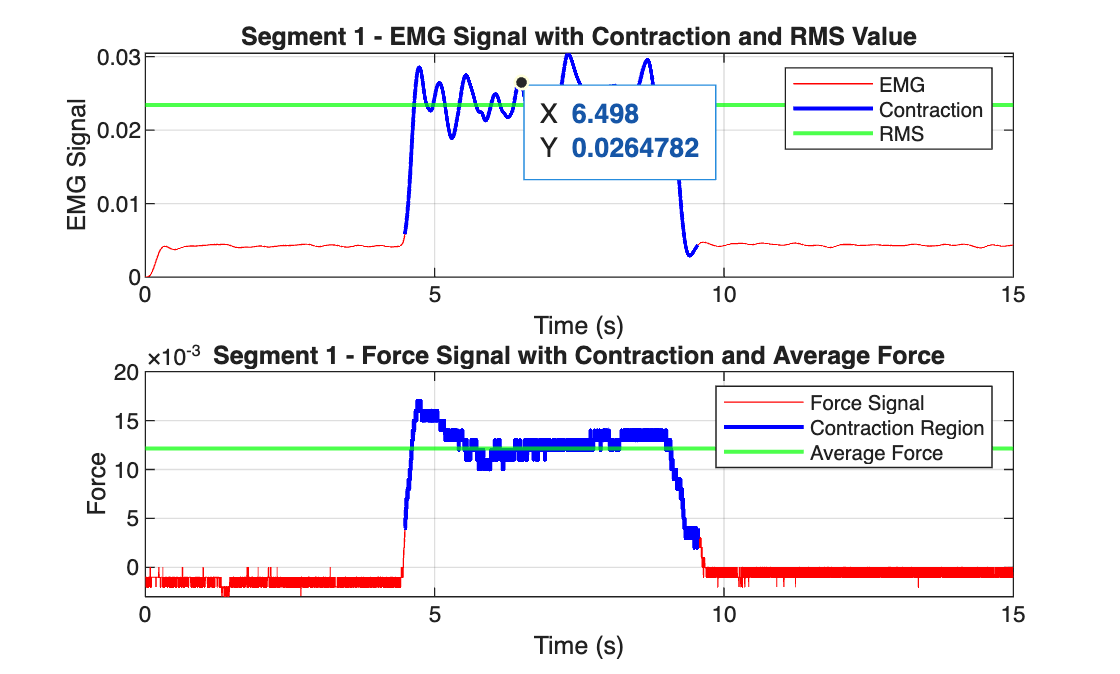

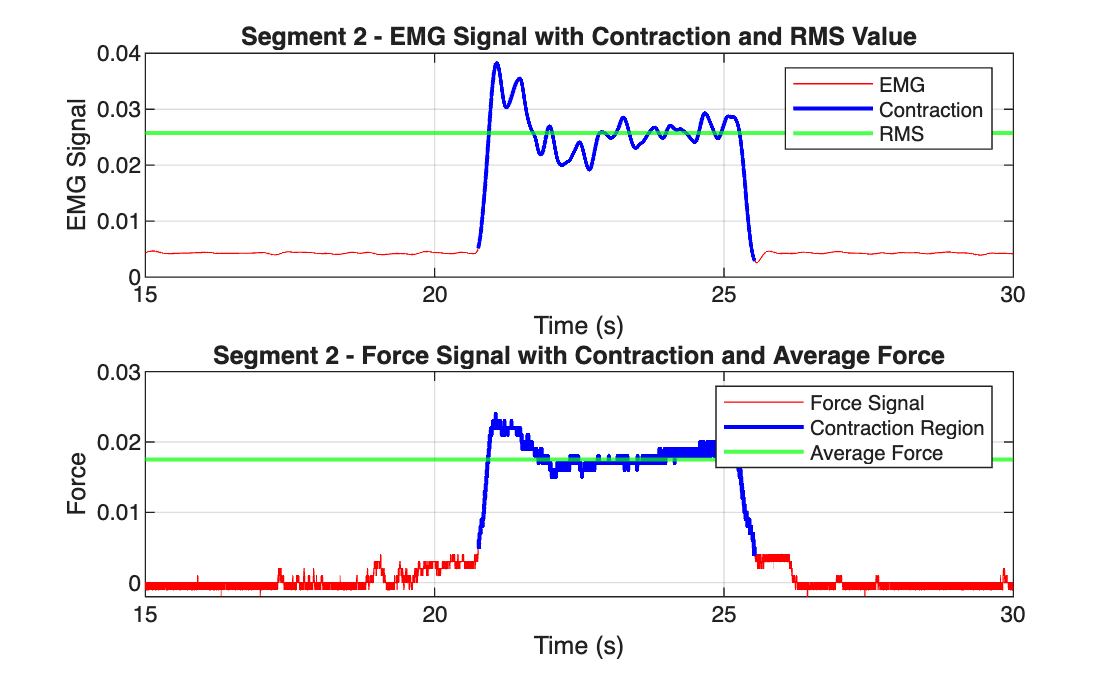

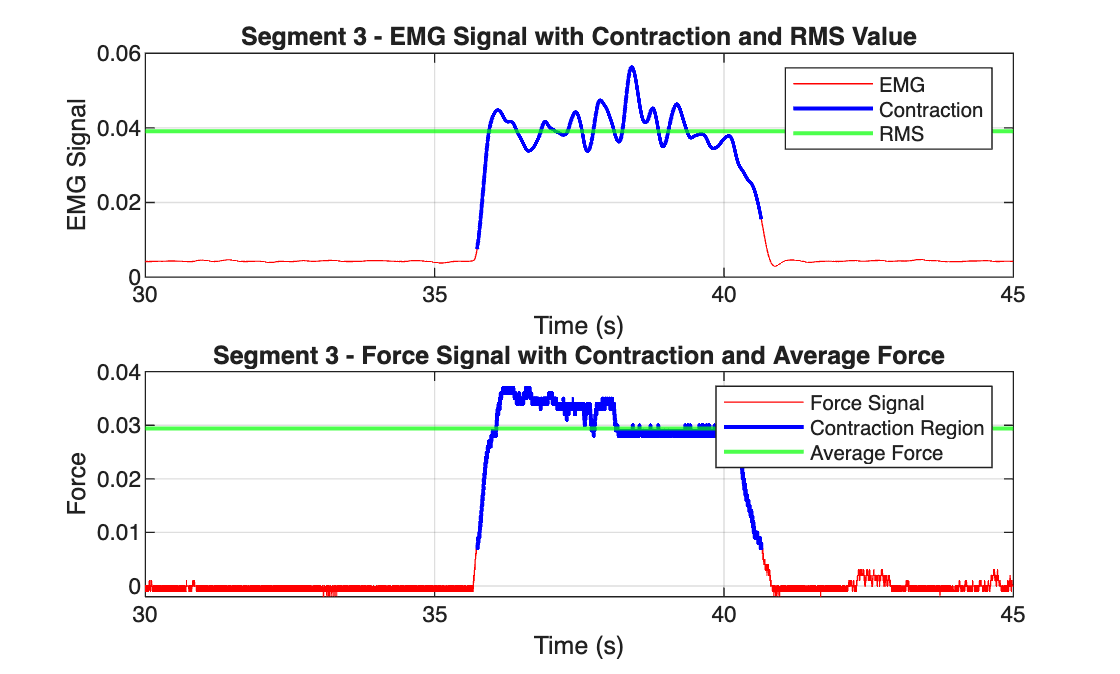

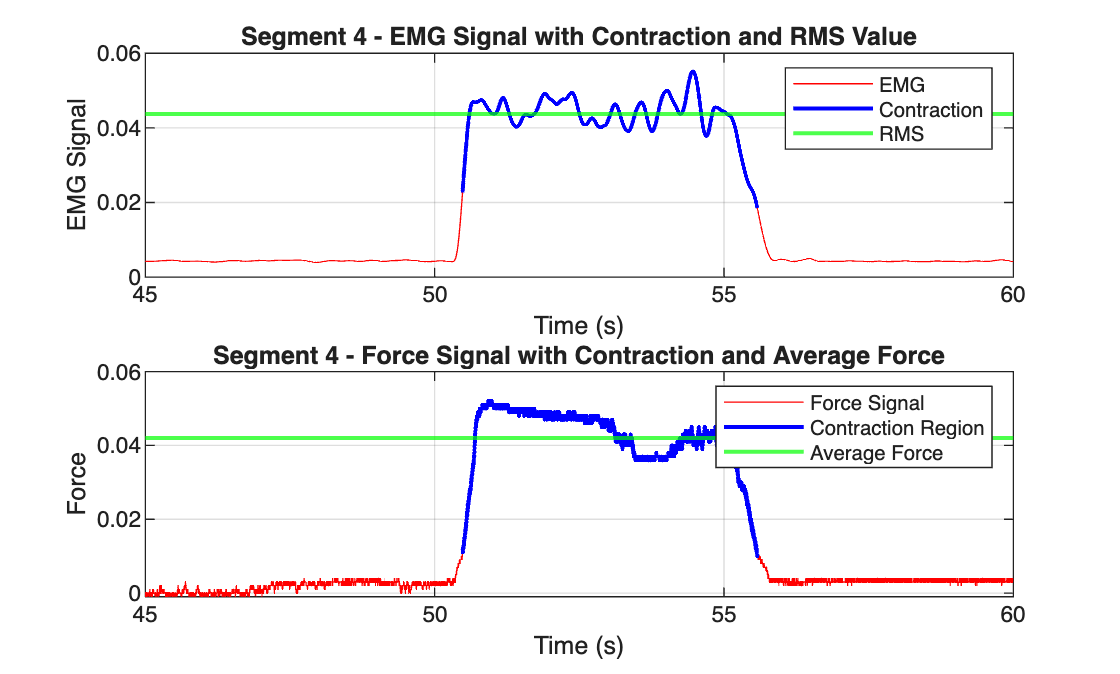

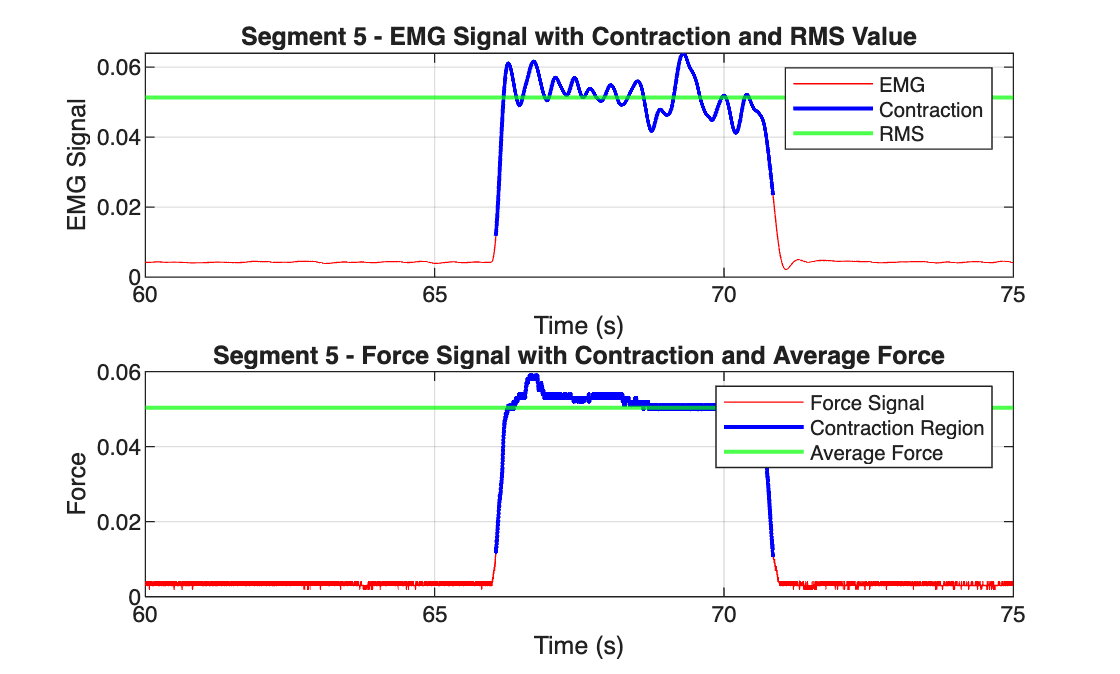

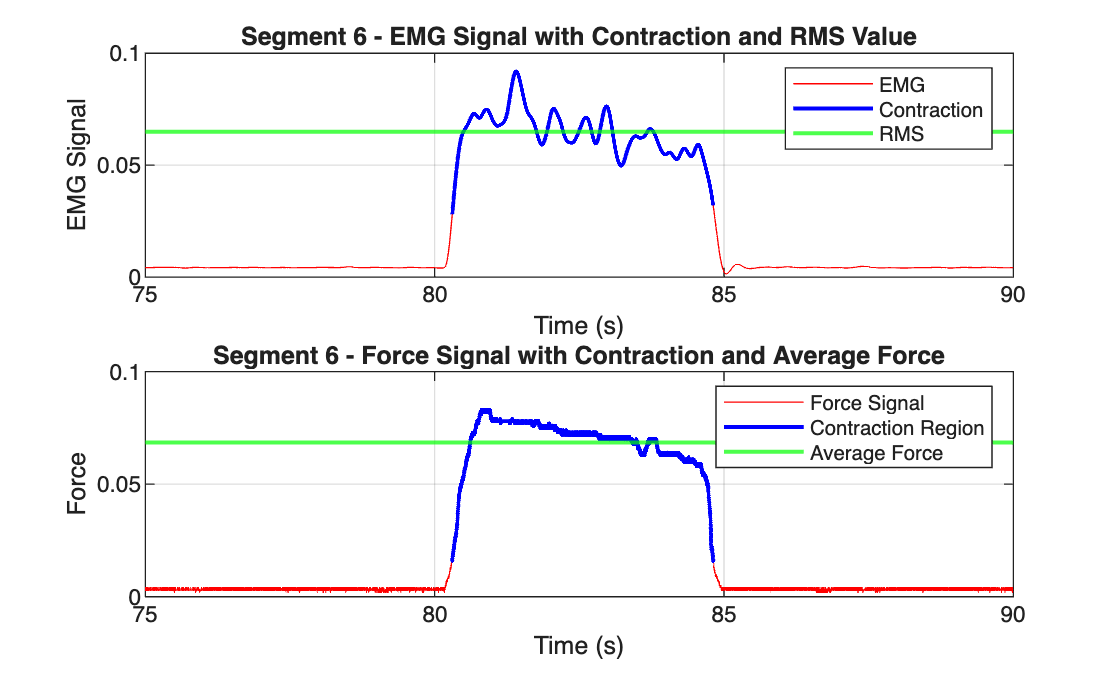

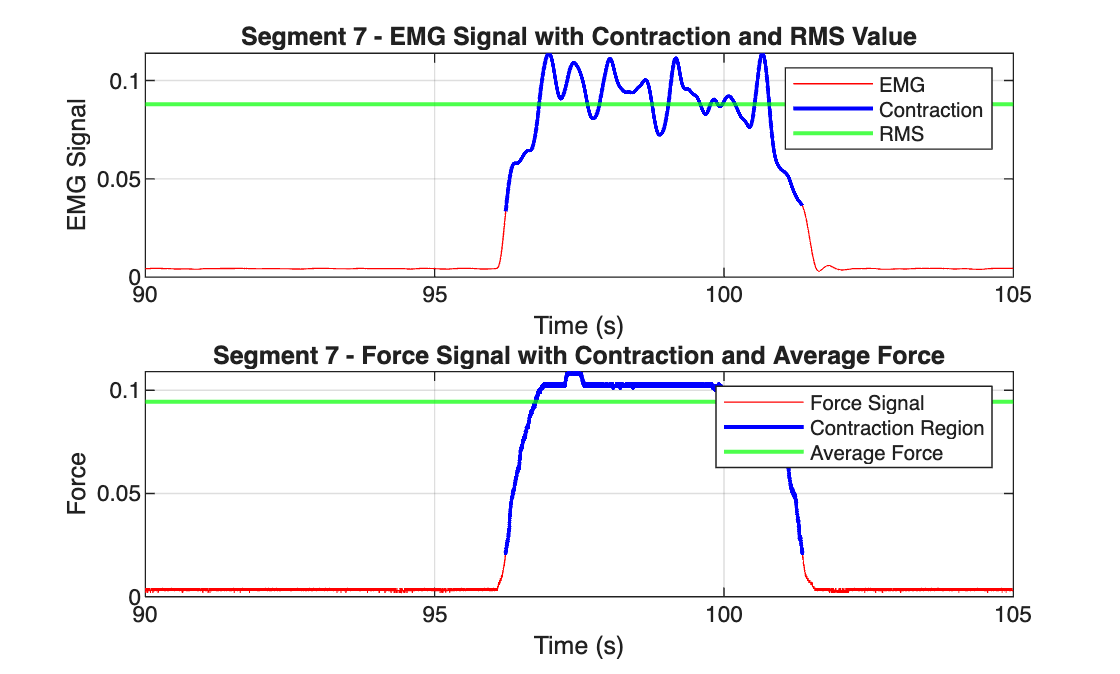

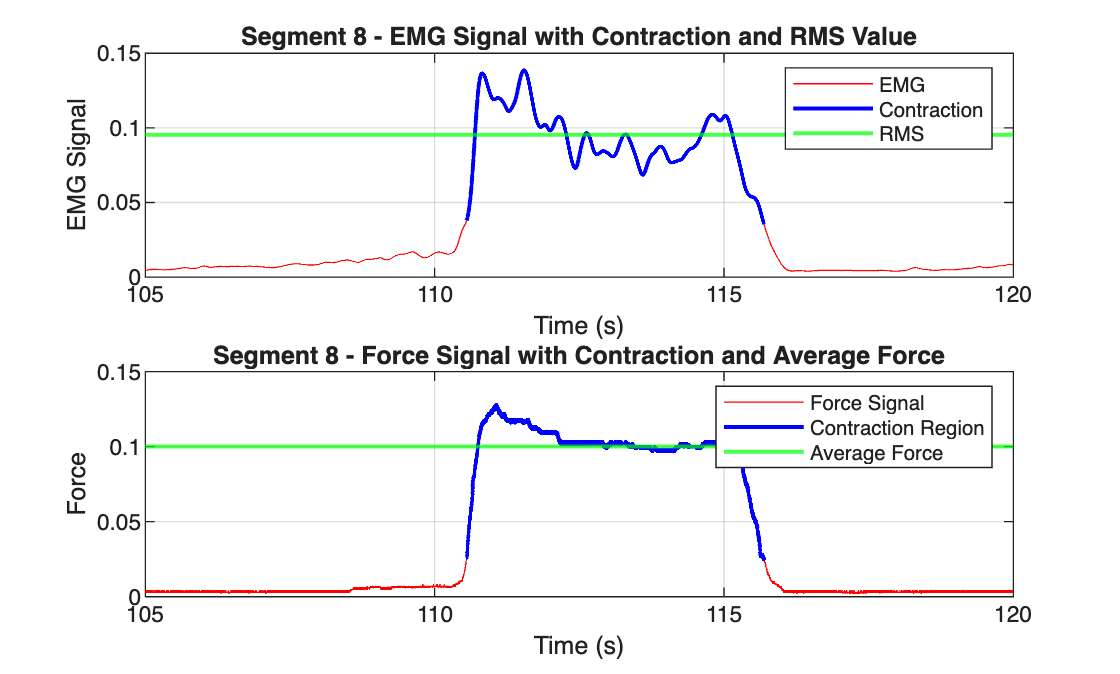

%6) Dividing signal into individual contractions
len= length(EMG_filtered);

% Reshape filtered EMG data into a 2D array with 30000 rows and 10 columns
EMG_r = reshape(EMG_filtered, [len/10, 10]);
% Reshape Force data into a 2D array with 30000 rows and 10 columns
Force_r = reshape(Force, [len/10, 10]);
% Reshape time vector into a 2D array with 30000 rows and 10 columns
t_r = reshape(t, [len/10, 10]);

RMS = zeros(10, 1);
average_force = zeros(10, 1);
contraction_indices = zeros(10, 2);

for i = 1:10
    limit = 0.2*max(Force_r(:, i));  % Define limit for force
    contractions = find(Force_r(:, i) > limit);  % Find contractions based on force signal

    contraction_indices(i, 1) = contractions(1);
    contraction_indices(i, 2) = contractions(end);
    RMS(i) = rms(EMG_r(contraction_indices(i, 1):contraction_indices(i, 2), i));
    average_force(i) = mean(Force_r(contraction_indices(i, 1):contraction_indices(i, 2), i));
    
    % Plot the EMG signal and force for the current segment
    figure;
    
    % Plot EMG signal
    subplot(2, 1, 1);
    plot(t_r(:, i), EMG_r(:, i), 'r'); % Plot the entire EMG signal in blue
    hold on;
    plot(t_r(contraction_indices(i, 1):contraction_indices(i, 2), i), ...
        EMG_r(contraction_indices(i, 1):contraction_indices(i, 2), i), 'b', 'LineWidth', 1.5); % Plot the contraction region in red
    yline(RMS(i), 'g', 'LineWidth', 1.5); % Add a horizontal line to indicate the RMS value
    xlabel('Time (s)');
    ylabel('EMG Signal');
    title(['Segment ', num2str(i), ' - EMG Signal with Contraction and RMS Value']);
    legend('EMG', 'Contraction', 'RMS');
    grid on;
    hold off;

    % Plot force signal
    subplot(2, 1, 2);
    plot(t_r(:, i), Force_r(:, i), 'r'); % Plot the entire force signal in blue
    hold on;
    plot(t_r(contraction_indices(i, 1):contraction_indices(i, 2), i), ...
        Force_r(contraction_indices(i, 1):contraction_indices(i, 2), i), 'b', 'LineWidth', 1.5); % Plot the contraction region in red
    yline(average_force(i), 'g', 'LineWidth', 1.5); % Add a horizontal line to indicate the average force
    xlabel('Time (s)');
    ylabel('Force');
    title(['Segment ', num2str(i), ' - Force Signal with Contraction and Average Force']);
    legend('Force Signal', 'Contraction Region', 'Average Force');
    grid on;
    hold off;
end

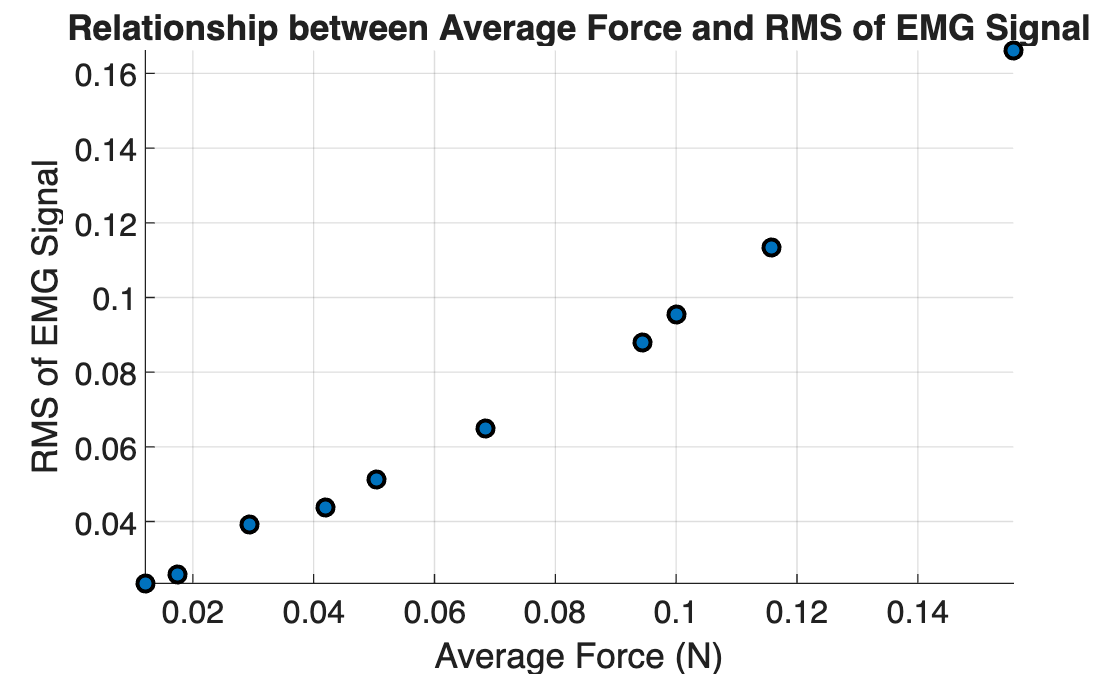


figure;
scatter(average_force, RMS, 'filled', 'MarkerFaceColor', [0 0.4470 0.7410], 'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
xlabel('Average Force (N)', 'FontSize', 12);
ylabel('RMS of EMG Signal', 'FontSize', 12);
title('Relationship between Average Force and RMS of EMG Signal', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', 12);
xlim([min(average_force) max(average_force)]);
ylim([min(RMS) max(RMS)]);


% Tabulate the results from the average force and RMS values
results_table = table((1:10)', average_force, RMS, ...
    'VariableNames', {'Segment', 'Average_Force_N', 'RMS_EMG'});
disp(results_table);

    Segment    Average_Force_N    RMS_EMG 
    _______    _______________    ________

       1          0.012138        0.023421
       2          0.017504        0.025753
       3          0.029413        0.039093
       4          0.042031        0.043696
       5          0.050392        0.051355
       6          0.068502        0.064968
       7          0.094405        0.087902
       8           0.10003        0.095334
       9           0.11571         0.11339
      10            0.1558         0.16611



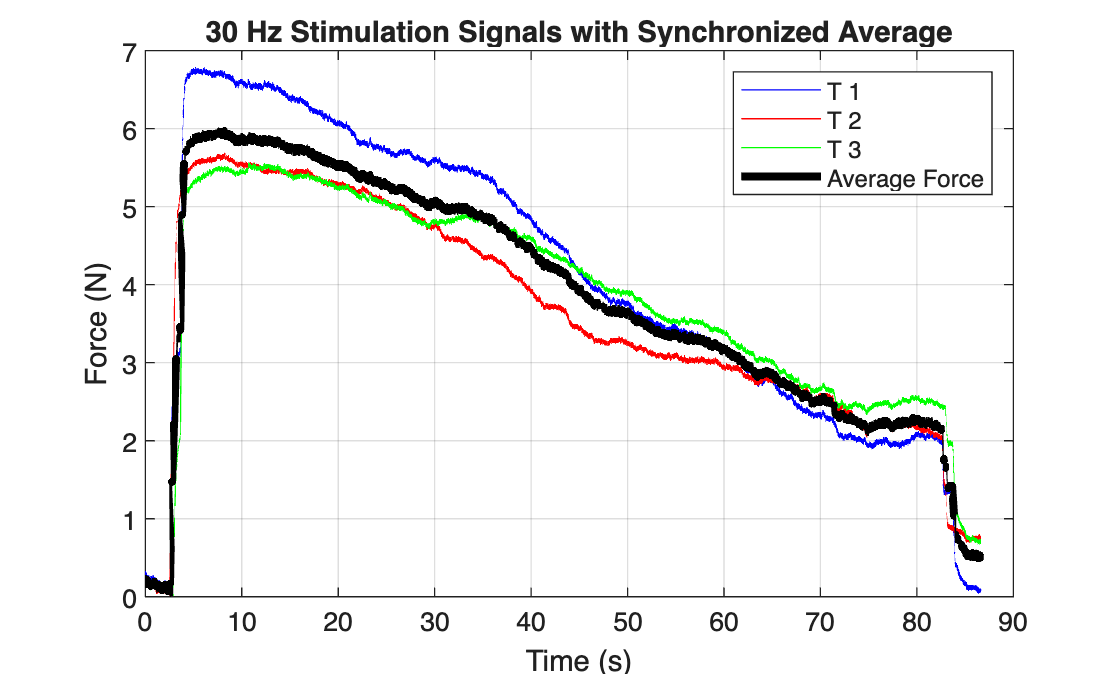

%% Part 2: Effects of stimulation frequency on muscle fatigue

% Find the shortest length for 30Hz data
min_length_30 = min([length(fData.force30_1), length(fData.force30_2), length(fData.force30_3)]);

% Trim all 30Hz trials to the shortest length
force30_1_trimmed = fData.force30_1(1:min_length_30);
force30_2_trimmed = fData.force30_2(1:min_length_30);
force30_3_trimmed = fData.force30_3(1:min_length_30);

tf30 = (0 : min_length_30 - 1) / fs_fatigue;

% Calculate the average and standard deviation for 30Hz trials
avg_force30 = (force30_1_trimmed + force30_2_trimmed + force30_3_trimmed) / 3;

% Plot the 30Hz data
figure;
plot(tf30, force30_1_trimmed, 'b', 'DisplayName', 'T 1');
hold on;
plot(tf30, force30_2_trimmed, 'r', 'DisplayName', 'T 2');
plot(tf30, force30_3_trimmed, 'g', 'DisplayName', 'T 3');
plot(tf30, avg_force30, 'k', 'LineWidth', 3, 'DisplayName', 'Average Force');
hold off;

xlabel('Time (s)');
ylabel('Force (N)');
title('30 Hz Stimulation Signals with Synchronized Average');
legend('show');
grid on;

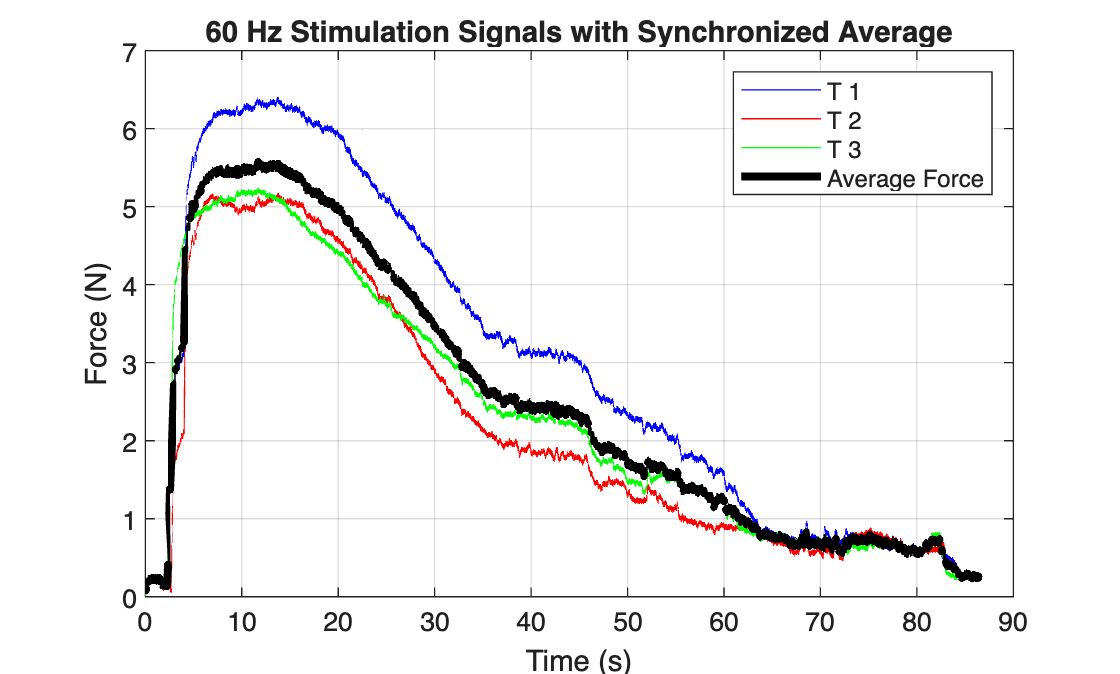


% Repeat the same process for 60Hz data
min_length_60 = min([length(fData.force60_1), length(fData.force60_2), length(fData.force60_3)]);

% Trim all 60Hz trials to the shortest length
force60_1_trimmed = fData.force60_1(1:min_length_60);
force60_2_trimmed = fData.force60_2(1:min_length_60);
force60_3_trimmed = fData.force60_3(1:min_length_60);

% Create time vectors for the trimmed data
tf60 = (0 : min_length_60 - 1) / fs_fatigue;

% Calculate the average and standard deviation for 60Hz trials
avg_force60 = (force60_1_trimmed + force60_2_trimmed + force60_3_trimmed) / 3;

% Plot the 60Hz data
figure;
plot(tf60, force60_1_trimmed, 'b', 'DisplayName', 'T 1');
hold on;
plot(tf60, force60_2_trimmed, 'r', 'DisplayName', 'T 2');
plot(tf60, force60_3_trimmed, 'g', 'DisplayName', 'T 3');
plot(tf60, avg_force60, 'k', 'LineWidth', 3, 'DisplayName', 'Average Force');
hold off;

xlabel('Time (s)');
ylabel('Force (N)');
title('60 Hz Stimulation Signals with Synchronized Average');
legend('show');
grid on;

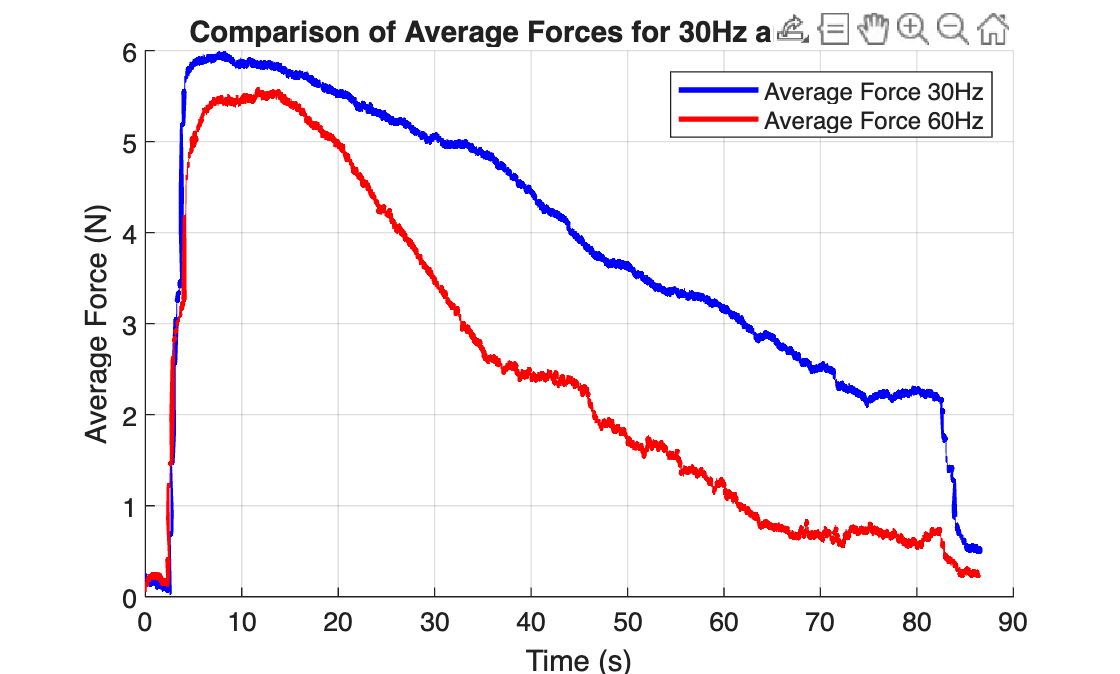


% Plot the average forces for 30Hz and 60Hz trials
figure;
hold on;
plot(tf30, avg_force30, 'b', 'LineWidth', 2, 'DisplayName', 'Average Force 30Hz');
plot(tf60, avg_force60, 'r', 'LineWidth', 2, 'DisplayName', 'Average Force 60Hz');
hold off;

xlabel('Time (s)');
ylabel('Average Force (N)');
title('Comparison of Average Forces for 30Hz and 60Hz Trials');
legend('show');
grid on;

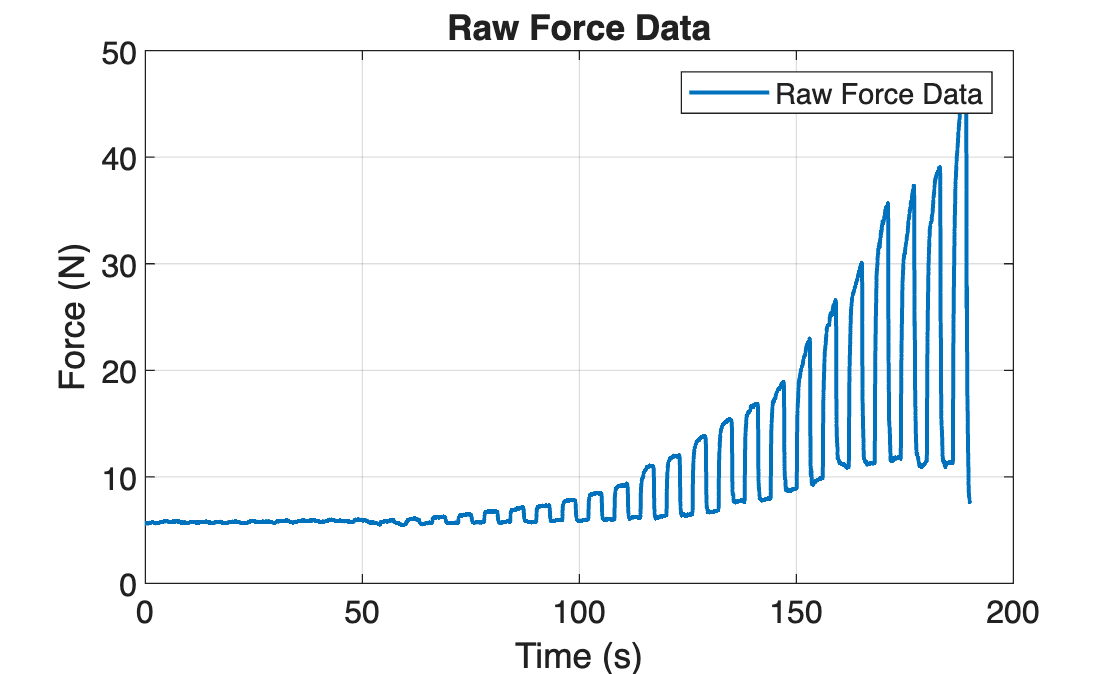

%% Part 3: Stimulation input - motor threshold investigation

% Define time of signal
t_stim_data = (0 : length(stim_data.force) - 1) / fs_simulation;

% Plot original force signal
figure;
plot(t_stim_data, stim_data.force, 'DisplayName', 'Raw Force Data', 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]);

xlabel('Time (s)', 'FontSize', 12);
ylabel('Force (N)', 'FontSize', 12);
title('Raw Force Data', 'FontSize', 14, 'FontWeight', 'bold');
legend('show');
grid on;
set(gca, 'FontSize', 12);

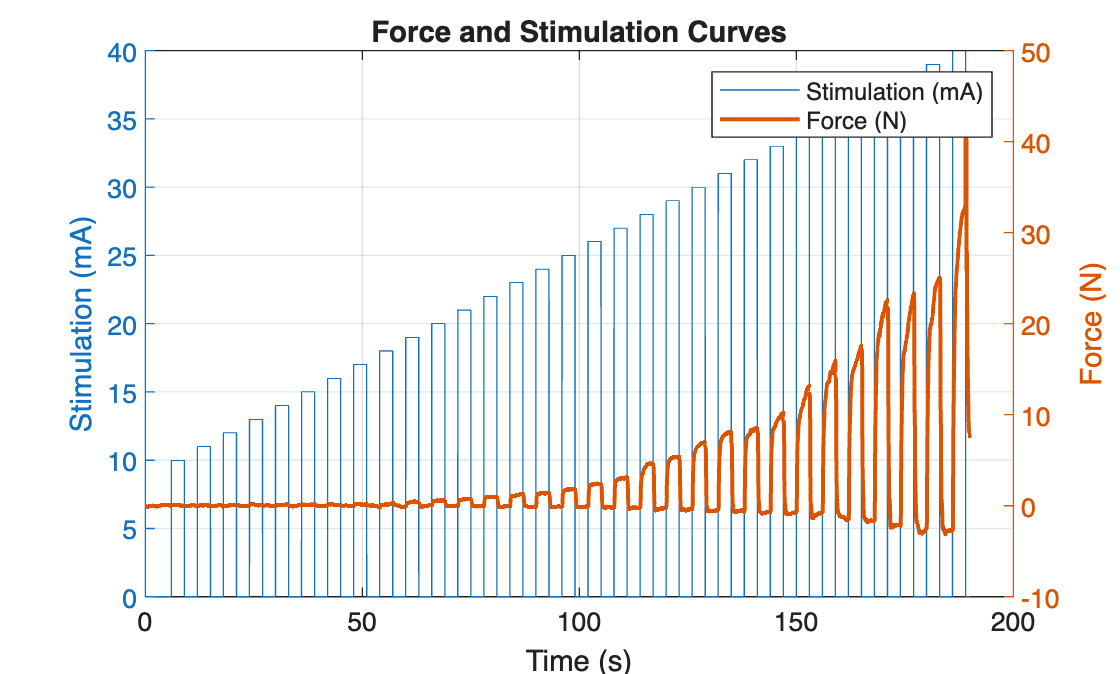

 
% Zero-mA Force: Subtract the dc-offset at 0mA stimulation
amount_of_points = 0;
offset_total = 0;
force_offset = stim_data.force;
i = 1;
start_i = 1;
while i ~= length(t_stim_data)
    if stim_data.stim_train(i) == 0
        amount_of_points = amount_of_points + 1;
        offset_total = offset_total + stim_data.force(i);
        i = i + 1;
    else
        offset = offset_total/amount_of_points;
        while stim_data.stim_train(i) ~= 0
            i = i + 1;
        end
        force_offset(start_i:i-1) = force_offset(start_i:i-1) - offset;
        amount_of_points = 0;
        offset_total = 0;
        start_i = i;
    end
end


% Plot the force and stimulation curves on the same chart. 
figure;
yyaxis left;
plot(t_stim_data, stim_data.stim_train, 'DisplayName', 'Stimulation (mA)');
ylabel('Stimulation (mA)');
yyaxis right;
plot(t_stim_data, force_offset, 'DisplayName', 'Force (N)', 'LineWidth', 1.5);
ylabel('Force (N)');
hold off;
xlabel('Time (s)');
title('Force and Stimulation Curves');
legend('show');
grid on;